circuit = Circuit('Circuits/RLC.txt');
netlist = circuit.get_netlist

netlist =     'Vcc 3 0 DC Vcc
     Vs 4 1 AC 0
     R2 3 2 1000
     R1 1 0 1000
     C1 4 0 0.000001
     C2 2 4 0.00001
     '


ELAB.analyze(circuit) % Symbolic

Symbolic analysis successful (0.806294 sec).


ELAB.ec2sd(circuit, 3, 2)

Symbolic transfer function calculated successfully (8.703400e-03 sec).


$$ans = \frac{v_{2}}{v_{3}}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\mathrm{Vcc}\,\left(C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1\right)}$$

ELAB.evaluate(circuit)


Numerical evaluation successful (0.264543 sec).


TF = ELAB.ec2tf(circuit, 3, 2)

Transfer function object created successfully (3.498030e-02 sec).

TF =
 
     1100 s + 100000
  ---------------------
  s^2 + 2100 s + 100000
 
Continuous-time transfer function.



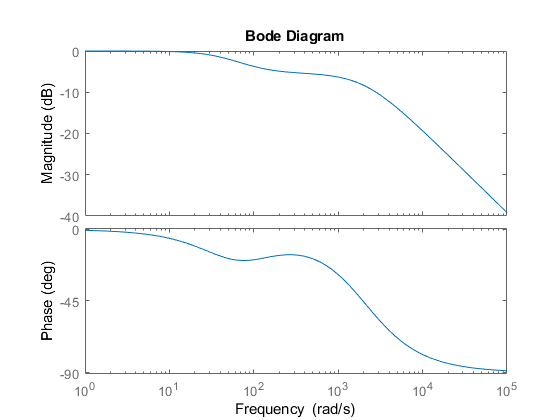

bode(TF);

circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=-\frac{R_{1}\,s\,\left(C_{1}\,\mathrm{Vs}-C_{2}\,\mathrm{Vcc}+C_{2}\,\mathrm{Vs}+C_{1}\,C_{2}\,R_{2}\,\mathrm{Vs}\,s\right)}{\sigma_{1}}\\ v_{2}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\sigma_{1}}\\ v_{3}=\mathrm{Vcc}\\ v_{4}=\frac{\mathrm{Vs}+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1 \end{array}$$